# Generate Logistic Model

nobs = 500;
seed = 1;
ntrials = 100;
fs = 50;
seeds = zeros(ntrials, 1);
x1 = NaN(ntrials, nobs); x2 = NaN(ntrials, nobs);

for i = 1:ntrials
    while sum(~isfinite(x1(i,:))) || sum(~isfinite(x2(i,:)))
        [x1(i, :), x2(i, :)] = generate_nonlinear_system(nobs, seed, "l-uni");
        seed = seed + 1;
    end
    seeds(i) = seed - 1;
end

## Granger causality test of Logistic system

G_cause(permute(cat(3, x1, x2), [3,2,1]), fs, "mode", "tf", "plot", 1, "report", 1);

## Generate coupled RL system

nobs = 1000;
seed = 1;
ntrials = 100;
fs = 100;
% 10 s of data

fig_folder = ".\Figures\0-Paper_figures\Nonlinear-systems\RL\";

downsample_ratio = 5;
fs2 = fs / downsample_ratio;

seeds = zeros(ntrials, 1);
X = NaN(3, ntrials, nobs); Y = NaN(3, ntrials, nobs);

for i = 1:ntrials
    while sum(~isfinite(X(:,i,:)), 'all') || sum(~isfinite(Y(:,i,:)), 'all')
        [X(:, i, :), Y(:, i, :)] = generate_nonlinear_system(nobs, seed, "RL");
        seed = seed + 1;
    end
    seeds(i) = seed - 1;
    
end

% X = X + rand(size(X)) *.5; Y = Y + rand(size(Y)) *.5;

x1 = squeeze(X(1,:,:)); x2 = squeeze(X(2,:,:)); x3 = squeeze(X(3,:,:));
y1 = squeeze(Y(1,:,:)); y2 = squeeze(Y(2,:,:)); y3 = squeeze(Y(3,:,:));

## Plot Data

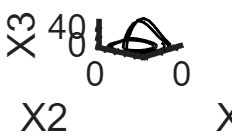

time = fs*4;
figure; plot3(x1(1,1:time), x2(1,1:time), x3(1,1:time), '-', "LineWidth", 2, "Color", "k");
ax = gca; set(ax, "fontSize", 25); set(ax, "LineWidth", 4);
xlabel("X1"); ylabel("X2"); zlabel("X3")
view([-50, 30])

% saveas(gcf, fig_folder + "X", "epsc");

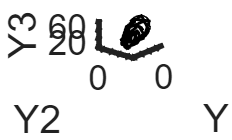


figure; plot3(y1(1,1:downsample_ratio:time), y2(1,1:downsample_ratio:time), y3(1,1:downsample_ratio:time), ...
    '-', ...
    "Markersize", 10, "LineWidth", 2, "Color", "k");
hold on;
plot3(y1(1,1:time), y2(1,1:time), y3(1,1:time), '--', ...
    "LineWidth", 1, "Color", "k");
% figure; plot3(y1(1,:), y2(1,:), y3(1,:), '-', "LineWidth", 4, "Color", "k");
ax = gca; set(ax, "fontSize", 25); set(ax, "LineWidth", 4);
xlabel("Y1"); ylabel("Y2"); zlabel("Y3")
view([-50, 30])

% saveas(gcf, fig_folder + "Y", "epsc");

## GC test on RL system

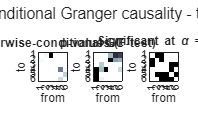


*** var_to_spwcgc... 1.317636 secs


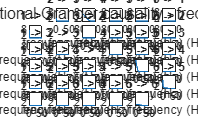

[f,~] = G_cause(permute(cat(1,X,Y), [1,3,2]), fs, "mode", "tf", "plot", 1, "report", 0, "seed", 5);

## GC test on the high-sampling-rate part

G_cause(permute(X, [1,3,2]), fs, "mode", 2, "plot", 1, "report", 0);

## Downsample and test MF causality

maxlag1 = 1.2;
maxlag2 = 1.3;

window_length = 30;
FFT_num = window_length;

STFT_abs = 1;

time_start = 1.5; time_end = 8.5;

     1



     2



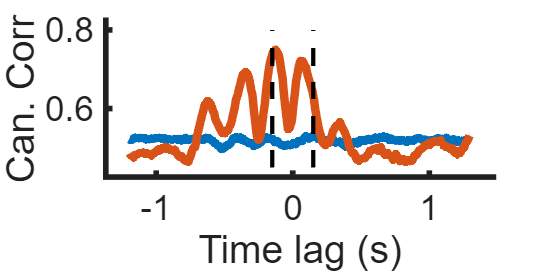

for xi = [1,]
    disp(xi)
    xi_others = setdiff([1,2,3], xi);
    % cals = MFTFCCA_compute_calibrations(squeeze(X(xi, :, :)), fs, downsample_ratio, ...
    %             window_length, time_start, time_end, maxlag1, maxlag2, STFT_abs);

    for yi = [2]
        
        disp(yi)
        [lags, r_0, r_su] = MFTFCCA_lagCC(squeeze(X(xi, :, :)), squeeze(Y(yi,:, 1:downsample_ratio:nobs)), fs, downsample_ratio, ...
                window_length, time_start, time_end, maxlag1, maxlag2, STFT_abs, "calibrations", [], "surrogate_num", 3, "partial_high_set", squeeze(X(xi_others, :, :)));
    end
end